Expected to gain insight on:

        Whether method even works

        Online computation reqmts

        Data reqmts for training

        Applicability online

%Specify State dims, output dims and input dims,
nx = 12;
ny = 12;
nu = 8;

%Set model and plant
%model = @TiltrotorDiscrete_model_Perturbed;
model = @TiltrotorDiscrete_model;
plant = @TiltrotorPlant_fd_Eul;

%create nmpc object
nlobj = nlmpc(nx, ny, nu);

In standard cost function, zero weights are applied by default to one or more OVs because there are fewer MVs than OVs.


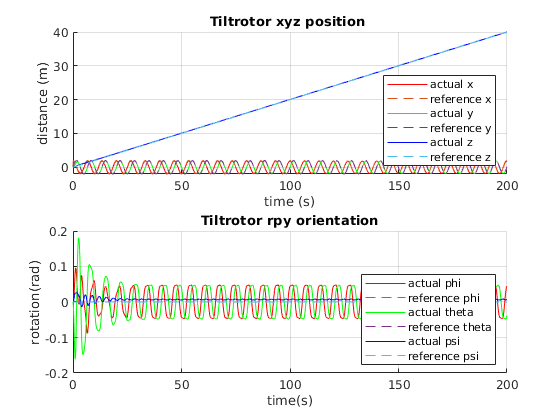

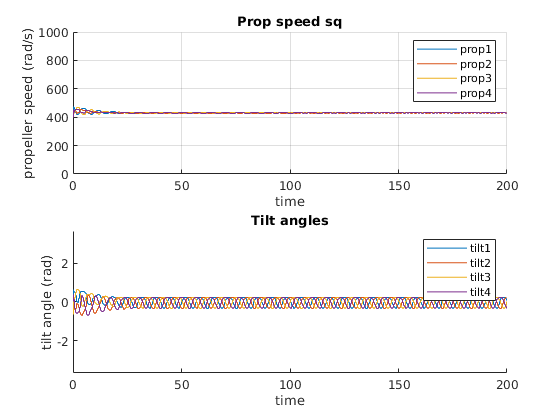

trajectory = function_handle with value:
    @HelixTrajectory


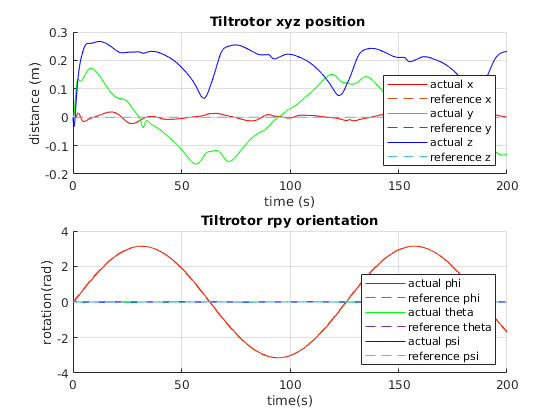

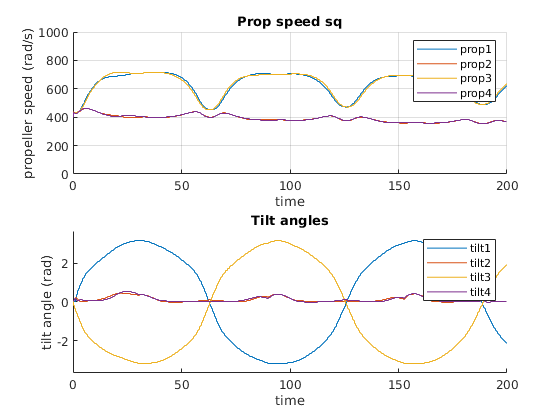

trajectory = function_handle with value:
    @RotxTrajectory


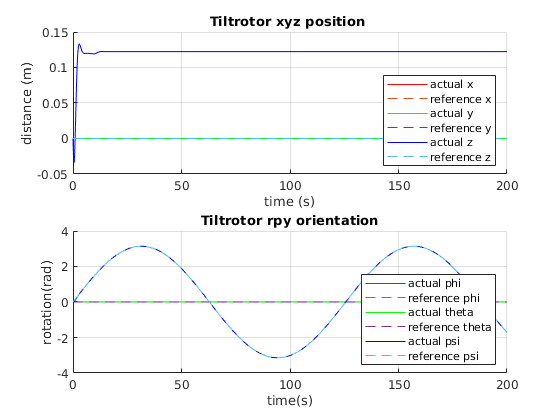

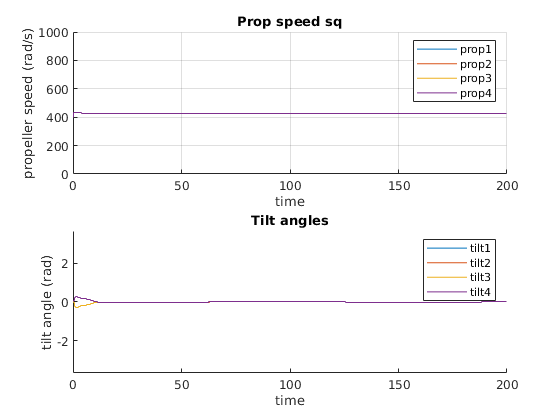

trajectory = function_handle with value:
    @RotzTrajectory


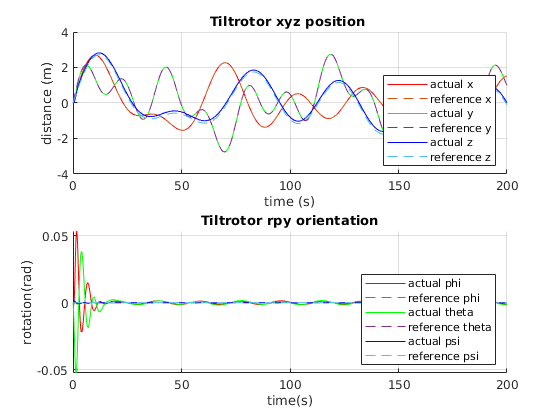

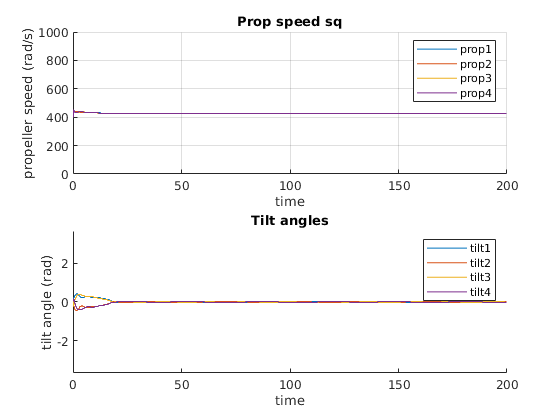

trajectory = function_handle with value:
    @DataTrajectory


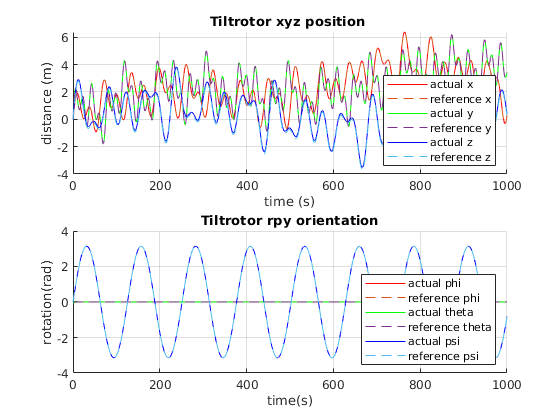

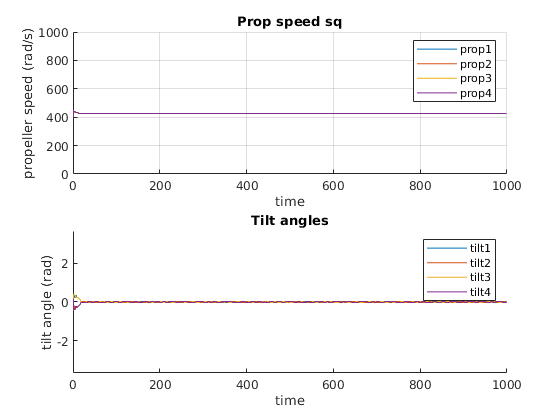

trajectory = function_handle with value:
    @ComplexTrajectory


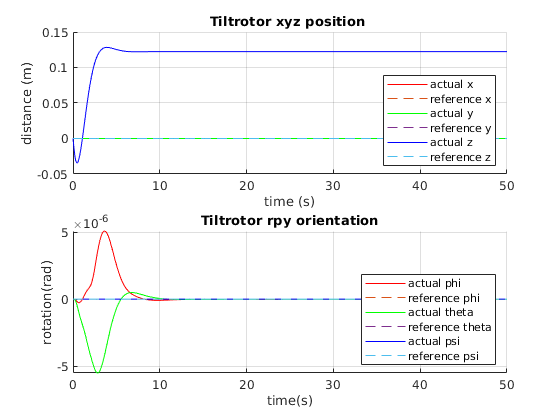

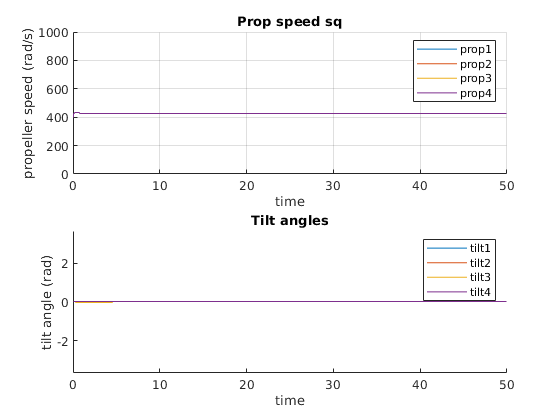

trajectory = function_handle with value:
    @StationaryTrajectory


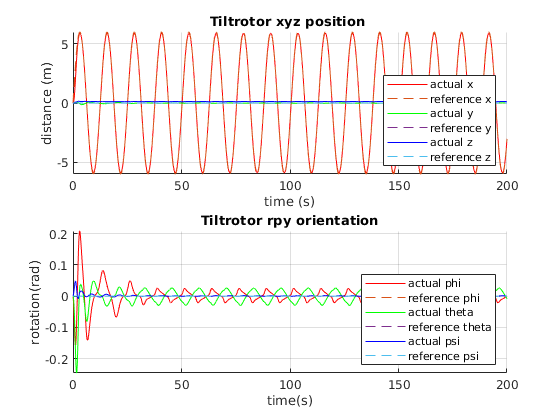

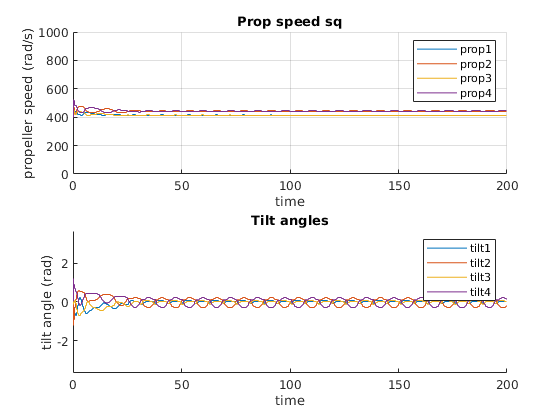

trajectory = function_handle with value:
    @SinxTrajectory


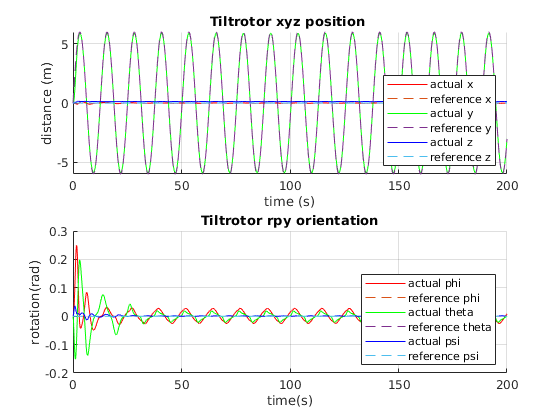

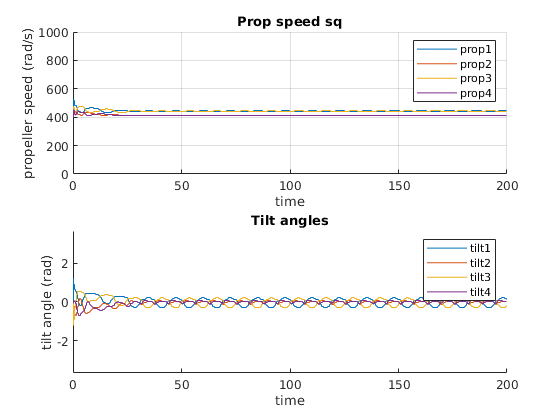

trajectory = function_handle with value:
    @SinyTrajectory


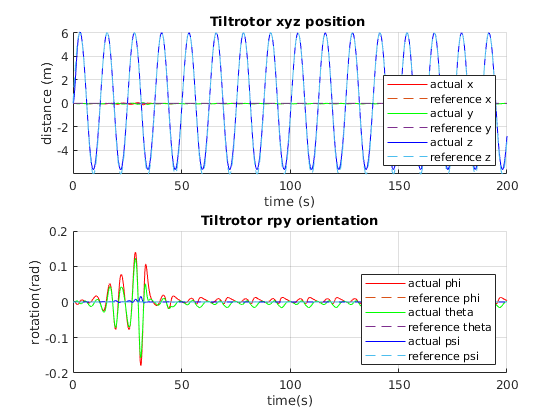

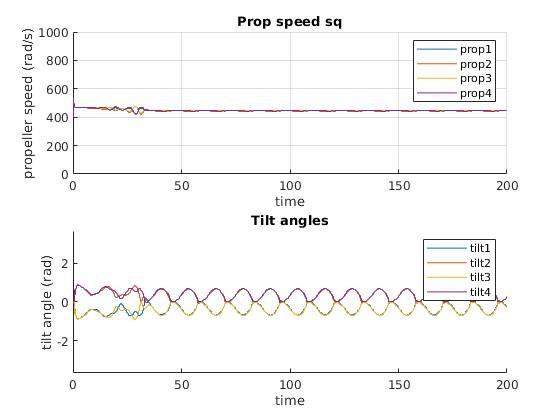

trajectory = function_handle with value:
    @SinzTrajectory



%input reference
%400 seems to stabilise convergence for all trajectories. setting 0 makes
%the control too unstable and system ends up losing control

nloptions.MVTarget = [0 0 0 0 0 0 0 0];
mv = [400 400 400 400 0 0 0 0];
%set initial guess to reference.

%Simulate the closed-loop system using the nlmpcmove function, specifying simulation options using an nlmpcmove object.

%trajectories = { @SinxTrajectory};
trajectories = {@HelixTrajectory @RotxTrajectory @RotzTrajectory @DataTrajectory @ComplexTrajectory...
   @StationaryTrajectory @SinxTrajectory  @SinyTrajectory @SinzTrajectory};

%dists = {@no_dist @const_dist @ge_dist};% @sigmoid_dist};
F_dist = @ge_dist2;

%Durations = [2];
%Durations = [20 20 20 20 20 20 20 20 20];
Durations = [200 200 200 200 1000 50 200 200 200];
data = [];

for l=1:length(trajectories)
%Specify the prediction model state function using the function name.
nlobj.Model.StateFcn = model; 
nlobj.Model.IsContinuousTime = false;
nlobj.Model.NumberOfParameters = 1;

%sample time
%0.1 seems most stable for LTV + Suboptimal nlMPC. 0.05 causes instabilty,
%and >0.1, is not practically useful.
Ts = 0.1;
%Prediction_horizon

%~=1s lookahead.
p = 15;
%input horizon
m = 1;

% Set parameters to nmpc
nlobj.Ts = Ts;
nlobj.PredictionHorizon = p;
nlobj.ControlHorizon = m;

%input constraints (rad/s) ^2 and rads
nlobj.MV = struct('Min',{0;0;0;0;-pi;-pi;-pi;-pi},...
                  'Max',{1000;1000;1000;1000;pi;pi;pi;pi});

%motor upper bound needs to be high since there is a possibility that only
%2 or one motor needs to be used to hover e.g during roll
              
% Tracking costs
nlobj.Weights.OutputVariables = 10*[1 1 1 1 1 1 0 0 0 0 0 0];

%To prioritize targets, set the average MV tracking priority lower than the average OV tracking priority.
nlobj.Weights.ManipulatedVariables = [8e-5 8e-5 8e-5 8e-5 ...
                                      0.1 0.1 0.1 0.1];

% penalize aggressive control actions by specifying tuning weights for the MV rates of change.
nlobj.Weights.ManipulatedVariablesRate = [0.1 0.1 0.1 0.1 ...
                                          0.5 0.5 0.5 0.5];

nlobj.Optimization.RunAsLinearMPC='TimeVarying';
                                      
nloptions = nlmpcmoveopt;
nloptions.Parameters = {Ts} ;

    % Specify the initial state
    x = [0;0;0;0;0;0;0;0;0;0;0;0];
    s0 = zeros(20,1);

    nloptions = nlmpcmoveopt;
    nloptions.Parameters = {Ts} ;
    
    nloptions.MVTarget = [0 0 0 0 0 0 0 0];
    mv = [400 400 400 400 0 0 0 0];
    
    Duration = Durations(l);
    hbar = waitbar(0,'Simulation Progress:');
    trajectory = trajectories{l};
    
    xHistory = x';
    sHistory = s0';
    
    xpredHistory = zeros(size(x'));
    xdotHistory = zeros(size(x')); 
    xdotpredHistory = zeros(size(x'));
    xdotnnpredHistory = zeros(size(x'));
    yrefHistory = zeros(size(x'));
  
    lastMV = mv;
    uHistory = lastMV;
    
    costs = zeros(Duration/Ts,1);
    elapsed_times = zeros(Duration/Ts,1);

    for k = 1:(Duration/Ts)
        % Set references for previewing
        t = linspace(k*Ts, (k+p-1)*Ts,p);
        
        % Compute the control moves with reference previewing.
        yref = trajectory(t);
        yrefHistory(k+1,:) = yref(:,1)';
        
        xk = xHistory(k,:);
        sk = sHistory(k,:);
        
        tic;
        [uk,nloptions,info] = nlmpcmove(nlobj,xk,lastMV,yref',[],nloptions);
        elapsed_times(k) = toc;
           
        %disturbance force
        %Nominal Thrust
        %https://link.springer.com/article/10.1007/s41315-019-00098-z (5)
        
        sdot = plant(sk',uk,F_dist(xk,uk));
        xdotHistory(k+1,:) = sdot(1:12)';
        xdotpredHistory(k+1,:) = TiltrotorModel_Eul(xk',uk);
        
        waitbar(k*Ts/(Duration),hbar);
        uHistory(k+1,:) = uk';
        lastMV = uk;
        costs(k) = info.Cost;
    
        % Update states.
        ODEFUN = @(t,sk) plant(sk,uk,F_dist(xk,uk));
        [TOUT,YOUT] = ode45(ODEFUN,[0 Ts], sHistory(k,:)');
        sHistory(k+1,:) = YOUT(end,:);
    
        xHistory(k+1,:) = sHistory(k+1,1:12);
        
        % Internal model for prediction.
        YOUT2 = model(xk',uk,Ts);
        xpredHistory(k+1,:) = YOUT2';
        
    end

datai=  [xHistory(5:end,:) xpredHistory(5:end,:) xdotHistory(5:end,:) xdotpredHistory(5:end,:) uHistory(5:end,:)];
data = [data; datai];
close(hbar)

time = 0:Ts:Duration;
yreftot = trajectory(time)';
plothistories(time,xHistory,yrefHistory,uHistory);
display(trajectory);
end

save('datacollection29_1_dist_ge2');
save('fd_Eul_LTV_data_1_dist_ge2','data');